This livescript is to be used to develop the script that will allow to generate the graphs. This just allows for easier debugging and section by section visualization of results


clear;
close all;

% You can change these 2 variables by either reassigining the value in the
% variables or the slider 

% reassigning variable value 
load_cell_number = 3;
test_number = 1; % note that this is not the test TYPE (stepped loading, etc)

% slider 
load_cell_number = 1;
test_number = 3; % note that this is not the test TYPE (stepped loading, etc)

    
    MCU_T1_LC1_data =  readtable("SyncOutputFiles\MCUSteppedLoading_LC"+load_cell_number+"_T"+test_number+".csv");
    INSTRON_T1_LC1_data = readtable("SyncOutputFiles\InstronSteppedLoading_LC"+load_cell_number+"_T"+test_number+".csv");
    % column 9: load information
    % column 1: time information
    
    % plotting of the data separately at first
    
    % MCU Data
    
    % loading data into vectors
    MCU_load = MCU_T1_LC1_data{:,2};
    MCU_time = MCU_T1_LC1_data{:,1}';
    
    Instron_load = INSTRON_T1_LC1_data{:,2};
    %Instron_load_scaled = Instron_load.*(1000/1.3831);
    Instron_time = INSTRON_T1_LC1_data{:,1};
    
    
    
    % store the step loads in Newton units (N) in an array which is going to be used in the outer
    % for-loop and also for referencing the threshold in the inner for-loop 
    step_loads_force = [10.00...  
                        20.00...  
                        40.00...  
                        70.00...  
                        100.00... 
                        200.00... 
                        400.00... 
                        700.00... 
                        1000.00... 
                        1236.00... 
                        1500.00].';
    
    % adjust the tolerances for each step load 
    tolerance_each_step =[0.00...   % 10N
                          0.00...   % 20N
                          0.00 ...  % 40N
                          0.00...   % 70N
                          0.00 ...  % 100N
                          0.00...   % 200N
                          0.00...   % 400N
                          0.00...   % 700N
                          0.00...   % 1000N
                          0.5...    % 1236N
                          0.5].';   % 1500N
    
    step_duration = 5.00; %duration of the instron step load 
    
    average_loads_each_step = zeros(length(step_loads_force),1,'double');
    time_indexes_each_step = zeros(length(step_loads_force),4,'double');
    
    
    MCU_time = MCU_time.'; % tranpose the MCU_data for easier formatting 
    
    for step_index = 1:length(step_loads_force) % beginning of outer for loop
        
        tol = tolerance_each_step(step_index); % cache the tolerance value for each step load through an index
        
        %%% Getting the time in the Instron load where it just exceeds the defined step load Step_loads_force(index) %%%%%%%
        for index = 1:length(Instron_load)
               
                if (Instron_load(index) > (step_loads_force(step_index)-tol)) % added a tolerance which can be adjusted in the tolerance_each_step array since Instron might not reach the exact load
    
                    break; 
                else
                    timestamp_start_index = index; %keep overwriting the index
                end
        end 
        
        %%% Cache the start and end time of the step load from Instron data %%%%%%%
        timestamp_start_val = Instron_time(timestamp_start_index); % start of step duration time from Instron_time data
        timestamp_end_val = timestamp_start_val + step_duration; % end of step duration time from Instron_time data
        
       % MCU_time = MCU_time.' ; %transpose matrix to be column vector to avoid formatting issues 
        
        % Find the MCU START time for a specific step load via the MCU data that 
        % is similar to the Instron START time and store the index 
        for index = 1:length(MCU_time)
        
                if (MCU_time(index) > (timestamp_start_val + 0.001)) % past the plateau Instron_load step
                    break;
                else
                    MCU_time_index_start = index; %keep overwriting the index
                end
        end 
        
        % Find the MCU END time for a specific step load via the MCU data that 
        % is similar to the Instron END time and store the index 
        for index = MCU_time_index_start :length(MCU_time)
          
                if (MCU_time(index) > (timestamp_end_val + 0.001)) %past the plateau Instron_load step
                    break;
                else
                    MCU_time_index_end = index; %keep overwriting the index
                end
        end
        
        % These assignment are for storing the timeindexes for the Instron and MCU into the zero array of time_indexes each step
        time_indexes_each_step(step_index,1) = timestamp_start_val;                     % 1st column for storing instron time start  
        time_indexes_each_step(step_index,2) = timestamp_end_val;                       % 2nd column for storing instron time end  
        time_indexes_each_step(step_index,3) = MCU_time(MCU_time_index_start);          % 3rd colum for storing MCU time start  
        time_indexes_each_step(step_index,4) = MCU_time(MCU_time_index_end);            % 4th colum for storing MCU time end 
        
        %overwrite the zero array each time for each step load and store the average uncallibrated load at each load step
        average_loads_each_step(step_index,1)= mean(MCU_load(MCU_time_index_start:MCU_time_index_end,1)); 
    
    end % end of outer for loop 
    
    %%%%%%%%%%%%
    %%%TABLES%%%
    %%%%%%%%%%%%
    
    % display the load cell readings time indexes for ... 
    % Reference StepLoad_Value from Instron (1st Col), 
    % Uncallibrated Average values @ step loads (2nd Col), 
    % Instron_start (3rd Col), 
    % Instron_end (4th Col)
    % MCU_start (5th Coll) 
    % MCU_end (6th Col) 
    % at the respective step loads in a table called S
    VarNames = {'Stepload Value', 'Mean Uncallibrated Value','Instron StartTime', 'Instron EndTime', 'MCU StartTime', 'MCU EndTime'};
    S = table(step_loads_force(:,1), ...
        average_loads_each_step(:,1), ...
        time_indexes_each_step(:,1), ...
        time_indexes_each_step(:,2), ...
        time_indexes_each_step(:,3), ...
        time_indexes_each_step(:,4), 'VariableNames',VarNames)

S = 11×6 table
    Stepload Value    Mean Uncallibrated Value    Instron StartTime    Instron EndTime    MCU StartTime    MCU EndTime
    ______________    ________________________    _________________    _______________    _____________    ___________

           10                     21389                20.573              25.573            20.498          25.492   
           20                     28423                31.316              36.316            31.289          36.283   
           40                     42696                41.959              46.959            41.902          46.897   
           70                     64145                52.383              57.383            52.337          57.331   
          100                     85609                62.887     

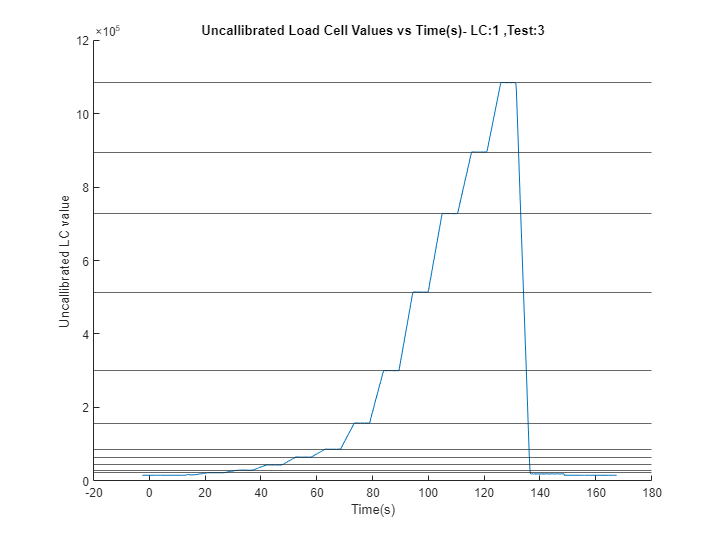

    
    %%PRINT Y_LINE of the average uncallibrated step loads%%%
    figure(2)
    hold on
    plot(MCU_time,MCU_load);
    for item = 1:length(average_loads_each_step)
        yline(average_loads_each_step(item,1))
    end
    % axes labelling 
    title("Uncallibrated Load Cell Values vs Time(s)- " + "LC:"  + load_cell_number +" ,Test:" + test_number);
    xlabel("Time(s)");
    ylabel("Uncallibrated LC value");
    set(gcf,'position',[10,10,900,600]);
    
    hold off

    
    %create folder within directory
    mkdir Average_GradientOutputFiles_Gabriel;

    % specifiy pathname of the csv file that is written to AverageTimeIndex
    filename_table = "Average_GradientOutputFiles_Gabriel\"+ "Step_LC"+ load_cell_number + "_T" + test_number + ".csv"

filename_table = "AverageReadingTimeIndex\Step_LC1_T3.csv"

    % Write table to folder
   writetable(S,filename_table)

